## Solution and visualization

**Physical constants**

First, define the physical constants.

L = 0.66; % Domain length (m) (guitar strings are 26 inches)
T = 67; % String tension
rho = 1e-3; % String density



Now load the measured data for the harmonics

load fftSingleNoteAnalysis.mat

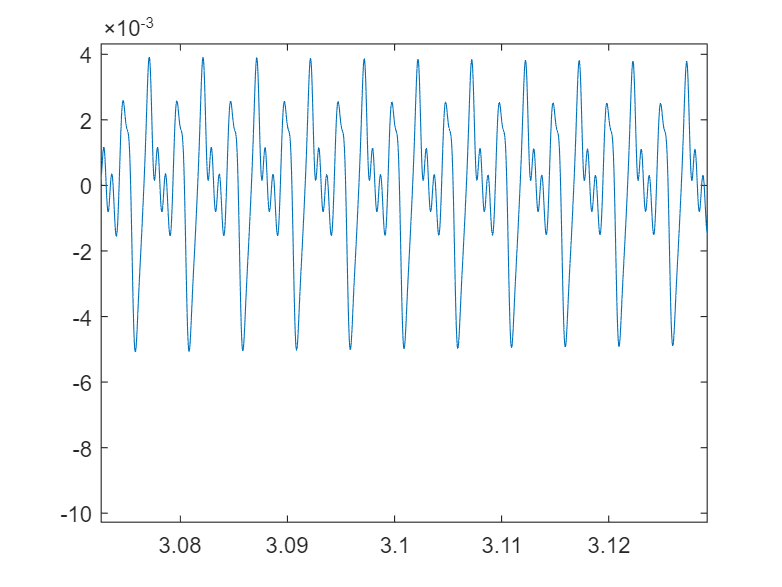

Nsamples = 5*Fs;
t = 1/Fs*(0:Nsamples-1)';
nFundamental = 2;
modeIndex = hFreq/hFreq(nFundamental); % Original
modeIndex = round(hFreq/hFreq(nFundamental)); % Rounded

% Variable tension
T = pchip([0,t(round(end/4)),t(end)],[60,63.5,67],t);

% Compute the reconstructed signal
yr = t*0;
for n = nFundamental:numel(h0)
    

    c = sqrt(T/rho); % Wave speed
    fh = modeIndex.*pi.*c/L;
    yr = yr + h0(n).*exp(gamma(n).*t).*cos(fh(:,n).*t + hPhase(n));
end    


plot(t,yr)

player = audioplayer(yr, Fs);
play(player);
